## **Introduction**

This is a live script. To use it, update and run the "input" section (ctrl+enter), then the "pre-processing" section.

You can then generate only the plots you like (you don't have to do all of them).

To navigate plots quicker, go to the Live Editor tab, and click on the "Go To" dropdown menu.

**NOTE**: this script requires the following measures to have been made and exported

**ObjectInclusionCount** -> Containing: Bacteria; To count: Spot_detection -> Name: SpotCount

**SpineCoordinates** -> Set SpineLength to parent: false

**SpineFeatures** -> Bacteria; Scaled: pixel

**Optional Measurement**:

**ObjectFeatures** -> Object class: Bacteria -> Feature: Mean -> Intensity: SOS_signal -> Name: normSOS

## Input

addpath(fileparts(matlab.desktop.editor.getActiveFilename))
cd(fileparts(matlab.desktop.editor.getActiveFilename)) % Add script folder to path (contains pre-processing script)
% addpath('D:\Daniel Thédié\Matlab\Bacmman_scripts\Spot_detection')

Bacmman_folder = '../../../BACMMAN/Timelapse/'; % Bacmman working directory
dataset_name = '210930_AL140_nocipro'; % Bacmman dataset name
prefix = 'Im'; % Prefix found in all images before the number (e.g. for Im1, Im2,... set prefix = 'Im';)
files_folder = '../../../Timelapse/210930/AL140_nocipro/'; % Folder where the original images are stored (only used to retrieve their timestamp)
bf_keyword = '_w10 Brightfield'; % Keyword to identify brightfield images

fps = 20; % Number of frames per second for the video

## Pre-processing

[dataCells, dataSpots, timepoints, xpoints, xpos_idx, direction, ypoints, y_heights, y_groups, fovNum,...
    nCellsFOV, nCells, spotFrac, spotFracFOV, zeroSpot, oneSpot, twoPlusSpot, sosFOV, cellLenFOV, cmap] =...
    spots_preproc(Bacmman_folder, dataset_name, prefix, files_folder, bf_keyword);

fprintf('Average number of cells per FOV: %.0f +/- %.0f\n', mean(nCellsFOV), std(nCellsFOV))

Average number of cells per FOV: 97 +/- 85


fprintf('Proportion of cells with spots (all FOVs): %.0f%% (n=%.0f)\n', spotFrac*100, nCells)

Proportion of cells with spots (all FOVs): 9% (n=15743)


fprintf('Average cell length: %.1f +/- %.1f µm\n', mean(dataCells.SpineLength, 'omitnan')*0.106, std(dataCells.SpineLength, 'omitnan')*0.106)

Average cell length: 2.9 +/- 1.0 µm


if ismember('normSOS', dataCells.Properties.VariableNames)
    fprintf('Average SOS signal: %.0f +/- %.0f\n', mean(dataCells.normSOS, 'omitnan'), std(dataCells.normSOS, 'omitnan'))
end

Average SOS signal: 43 +/- 26


### Scheme of the acquisition pattern

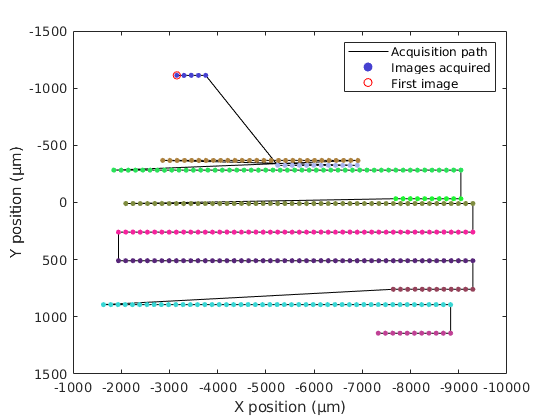

figure('Color', 'white')
hold on
plot(dataCells.asi_x, dataCells.asi_y, 'Color', 'k')
for i = 1:length(y_heights)
    x_data = xpoints(ypoints == y_heights(i));
    y_data = ypoints(ypoints == y_heights(i));
    scatter(x_data, y_data, 10, 'MarkerEdgeColor', cmap(i,:), 'MarkerFaceColor', cmap(i,:))
    scatter(dataCells.asi_x(1), dataCells.asi_y(1), 30, 'r')
end
hold off
box on
set(gca, 'YDir','reverse')
set(gca, 'XDir','reverse')
xlabel('X position (µm)')
ylabel('Y position (µm)')

legend('Acquisition path', 'Images acquired', 'First image')

### Number of cells recorded per FOV

figure('color','white')
scatter(fovNum, nCellsFOV, 15, 'filled')
box on
xlabel('FOV number')
ylabel('Number of cells recorded')
ylim([0 1.2*max(nCellsFOV)])

### Histogram of cell lengths

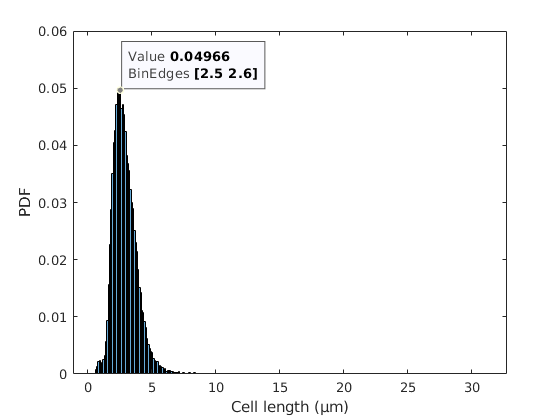

figure('Color', 'white')
histogram(dataCells.SpineLength*0.106, 'Normalization', 'probability')
xlabel('Cell length (µm)')
ylabel('PDF')

### Cell length vs time

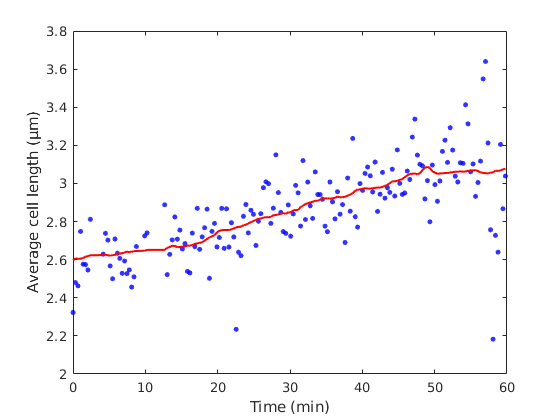

length_movmean = movmean(cellLenFOV*0.106, 50);
figure('Color', 'white')
hold on
scatter(minutes(timepoints), cellLenFOV*0.106, 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(minutes(timepoints), length_movmean, 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
xlabel('Time (min)')
ylabel('Average cell length (µm)')

### Histogram of SOS signal

if ismember('normSOS', dataCells.Properties.VariableNames)
    figure('Color', 'white')
    histogram(dataCells.normSOS, 'Normalization', 'probability', 'BinWidth', 200)
    xlabel('Mean SOS signal per cell')
    ylabel('PDF')
else
    fprintf('No SOS data found.\n')
end

### SOS signal vs time

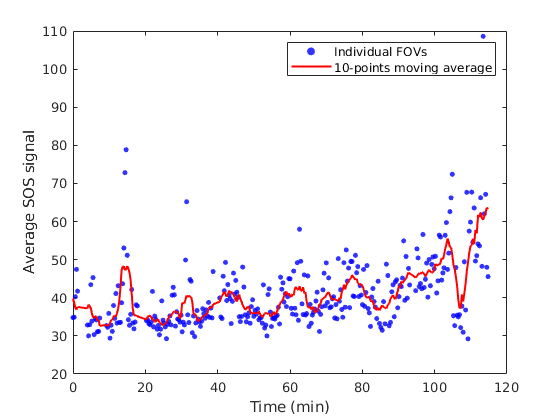

sos_movmean = movmean(sosFOV, 10);
figure('Color', 'white')
hold on
scatter(minutes(timepoints), sosFOV, 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(minutes(timepoints), sos_movmean, 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
xlabel('Time (min)')
ylabel('Average SOS signal')
legend('Individual FOVs', '10-points moving average')

### SOS signal vs X-position (i.e. cipro concentration)

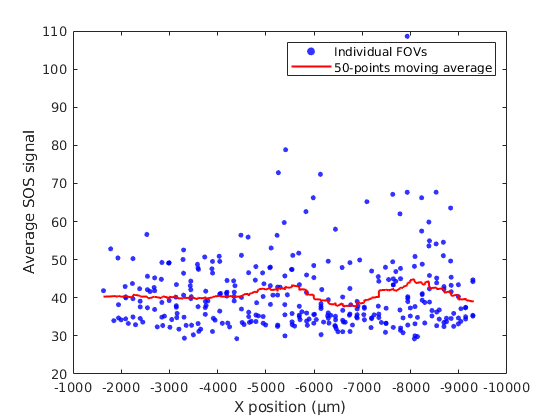

sosFOV_xpos = sosFOV(xpos_idx);
xinput = xpoints;
yinput = sosFOV_xpos;

figure('Color', 'white')
hold on
scatter(xinput, yinput, 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(xinput, movmean(yinput, 50), 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
xlabel('X position (µm)')
ylabel('Average SOS signal')
legend('Individual FOVs', '50-points moving average')
set(gca, 'XDir','reverse') % To plot the graph in the same direction as the acquisition goes (left to right)

### SOS signal vs X-position (left to right direction only)

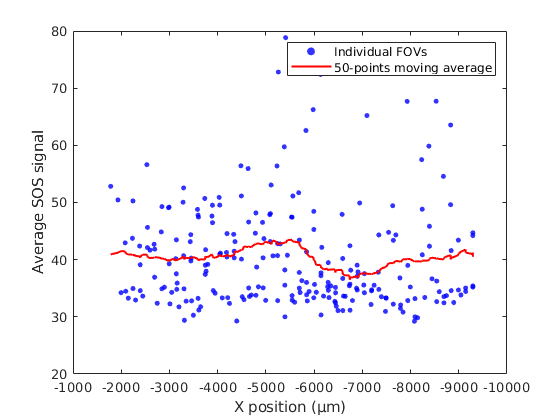

sosFOV_xpos = sosFOV(xpos_idx);
xinput = xpoints(~direction);
yinput = sosFOV_xpos(~direction);

figure('Color', 'white')
hold on
scatter(xinput, yinput, 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(xinput, movmean(yinput, 50), 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
xlabel('X position (µm)')
ylabel('Average SOS signal')
legend('Individual FOVs', '50-points moving average')
set(gca, 'XDir','reverse') % To plot the graph in the same direction as the acquisition goes (left to right)

### SOS signal vs X-position for each Y-position

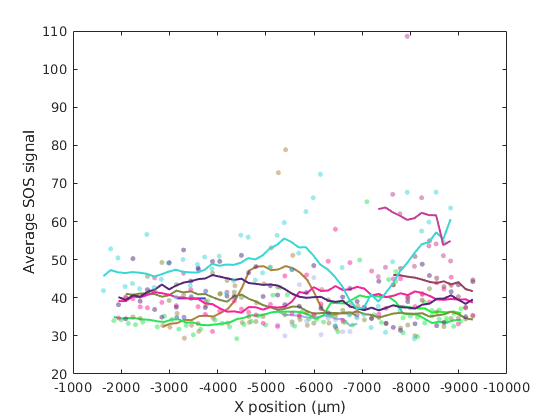

yinput = sosFOV(xpos_idx);

figure('Color', 'white')
hold on
for i = 1:length(y_heights)
    x_data = xpoints(ypoints == y_heights(i));
    y_data = yinput(ypoints == y_heights(i));
    scatter(x_data, y_data, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', cmap(i,:));
    plot(x_data, movmean(y_data, 10), 'LineWidth', 1.5, 'Color', cmap(i,:));
end
hold off
xlabel('X position (µm)')
ylabel('Average SOS signal')
set(gca, 'XDir','reverse')
box on

### SOS signal vs X-position for each Y-position (left to right direction only)

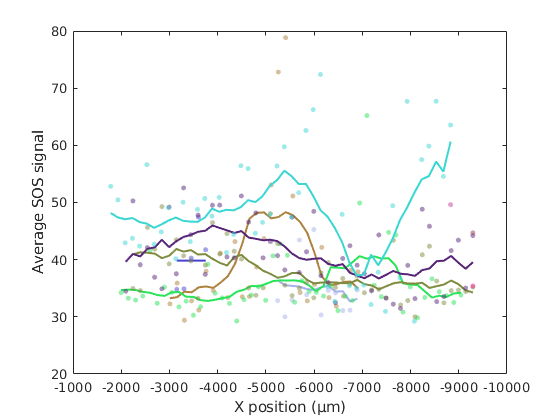

sosFOV_xpos = sosFOV(xpos_idx);
xinput = xpoints(~direction);
yinput = sosFOV_xpos(~direction);
ypoints_in = ypoints(~direction);

figure('Color', 'white')
hold on
for i = 1:length(y_heights)
    x_data = xinput(ypoints_in == y_heights(i));
    y_data = yinput(ypoints_in == y_heights(i));
    scatter(x_data, y_data, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', cmap(i,:));
    plot(x_data, movmean(y_data, 10), 'LineWidth', 1.5, 'Color', cmap(i,:));
end
hold off
xlabel('X position (µm)')
ylabel('Average SOS signal')
set(gca, 'XDir','reverse')
box on

### Cell length/SOS signal correlation

if ismember('normSOS', dataCells.Properties.VariableNames)
    figure('Color', 'white')
    scatter(cellLenFOV, sosFOV, 15, 'filled', 'MarkerFaceAlpha', 0.6, 'MarkerFaceColor', 'b');
    box on
    xlabel('Cell length (pixels)')
    ylabel('SOS signal (AU)')
end

### Spot_frac vs SOS signal correlation

if ismember('normSOS', dataCells.Properties.VariableNames)
    figure('Color', 'white')
    scatter(sosFOV, spotFracFOV, 15, 'filled', 'MarkerFaceAlpha', 0.6, 'MarkerFaceColor', 'b');
    box on
    xlabel('SOS signal (AU)')
    ylabel('Fraction of cells with immobile spots')
end

### Per cell, number of spots vs SOS signal

normSOS_perNspot = grpstats(dataCells.normSOS, dataCells.SpotCount, 'median');
if ismember('normSOS', dataCells.Properties.VariableNames)
    figure('Color', 'white')
    scatter(dataCells.normSOS, dataCells.SpotCount, 15, 'filled', 'MarkerFaceAlpha', 0.6, 'MarkerFaceColor', 'b')
    hold on
    plot(normSOS_perNspot, 0:length(normSOS_perNspot)-1, 'LineWidth', 1.5, 'Color', 'r')
    hold off
    xlabel('SOS signal (AU)')
    ylabel('Number of immobile spots')
    ylim([-0.5 length(normSOS_perNspot)+.5])
end

### SpotFrac & SOS signal moving means plotted together

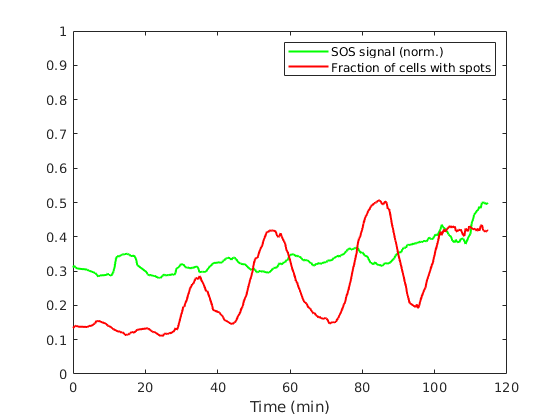

sos_movmean = movmean(sosFOV, 20);
spotFrac_mean = movmean(spotFracFOV, 20);
figure('Color', 'white')
plot(minutes(timepoints), sos_movmean/(2*max(sos_movmean)), 'LineWidth', 1.5, 'Color', 'g');
hold on
plot(minutes(timepoints), spotFrac_mean, 'LineWidth', 1.5, 'Color', 'r');
hold off
ylim([0 1])
xlabel('Time (min)')
legend('SOS signal (norm.)', 'Fraction of cells with spots')

### Cross-correlation between SOS signal and spotFrac

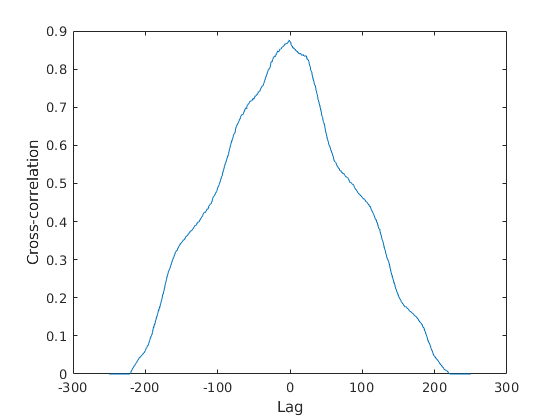

maxlag = 250;
[c, lags] = xcorr(sosFOV(60:280), spotFracFOV(60:280), maxlag, 'normalized');
% 60:280 <=> 25 to 100 min

figure('Color', 'white')
plot(lags, c)
xlabel('Lag')
ylabel('Cross-correlation')

### SOS signal vs time for different spotFrac

if ismember('normSOS', dataCells.Properties.VariableNames)
    figure('Color', 'white')
    hold on
    y = zeros(3, length(timepoints));
    for i = 1:length(timepoints)
        y(1, i) = mean(dataCells.normSOS(dataCells.TrueIdx == i & dataCells.SpotCount == 0));
        y(2, i) = mean(dataCells.normSOS(dataCells.TrueIdx == i & dataCells.SpotCount == 1));
        y(3, i) = mean(dataCells.normSOS(dataCells.TrueIdx == i & dataCells.SpotCount >= 2));
    end
    sosMovMeanZero = movmean(y(1,:), 10, 'omitnan');
    sosMovMeanOne = movmean(y(2,:), 10, 'omitnan');
    sosMovMeanTwo = movmean(y(3,:), 10, 'omitnan');
    scatter(minutes(timepoints), y(1,:), 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', 'k');
    scatter(minutes(timepoints), y(2,:), 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', 'b');
    scatter(minutes(timepoints), y(3,:), 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', 'm');
    plot(minutes(timepoints), sosMovMeanZero, 'LineWidth', 1.5, 'Color', 'k');
    plot(minutes(timepoints), sosMovMeanOne, 'LineWidth', 1.5, 'Color', 'b');
    plot(minutes(timepoints), sosMovMeanTwo, 'LineWidth', 1.5, 'Color', 'm');
    hold off
    box on
    xlabel('Time (min)')
    ylabel('Average SOS signal')
    legend('No spot','One spot','2 or more spots')
end

### Number of spots per cell histogram

figure('Color', 'white')
histogram(dataCells.SpotCount, 'Normalization', 'probability', 'BinWidth', 1,...
    'BinEdges', -0.5:1:max(dataCells.SpotCount)+0.5)
xlabel('Number of spots per cell')
ylabel('PDF')

### Time evolution of the number of spots per cell

zeroSpot_mean = movmean(zeroSpot, 50);
oneSpot_mean = movmean(oneSpot, 50);
twoSpot_mean = movmean(twoPlusSpot, 50);
figure('Color', 'white')
hold on
scatter(minutes(timepoints), zeroSpot, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', 'k');
scatter(minutes(timepoints), oneSpot, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', 'b');
scatter(minutes(timepoints), twoPlusSpot, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', 'm');
plot(minutes(timepoints), zeroSpot_mean, 'LineWidth', 1.5, 'Color', 'k');
plot(minutes(timepoints), oneSpot_mean, 'LineWidth', 1.5, 'Color', 'b');
plot(minutes(timepoints), twoSpot_mean, 'LineWidth', 1.5, 'Color', 'm');
hold off
box on
xlabel('Time (min)')
ylabel('Proportion of cells containing 0, 1 or more spots')
ylim([0 1.3])
legend('No spot','One spot','2 or more spots')

### Histogram of fraction of cells with spots per FOV

figure('Color', 'white')
histogram(spotFracFOV, 'Normalization', 'probability', 'BinWidth', 0.02)
xlabel('Fraction of cells with spots per FOV')
ylabel('PDF')
xlim([0 1])

### Time evolution of the fraction of cells with spots per FOV

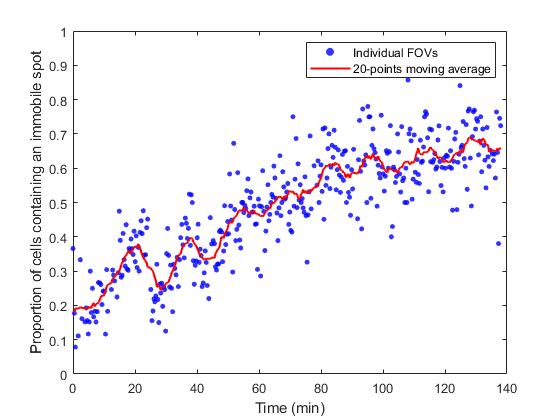

spotFrac_mean = movmean(spotFracFOV, 20);

figure('Color', 'white')
hold on
scatter(minutes(timepoints), spotFracFOV, 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(minutes(timepoints), spotFrac_mean, 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
xlabel('Time (min)')
ylabel('Proportion of cells containing an immobile spot')
ylim([0 1])
legend('Individual FOVs', '20-points moving average')

### spotFrac vs X-position

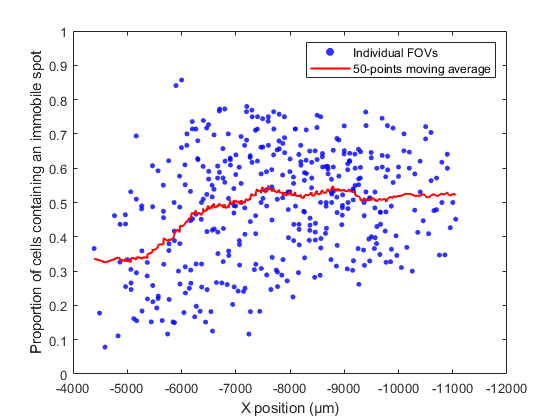

spotFrac_mean_xpos = movmean(spotFracFOV(xpos_idx), 50);
figure('Color', 'white')
hold on
scatter(xpoints, spotFracFOV(xpos_idx), 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(xpoints, spotFrac_mean_xpos, 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
set(gca, 'XDir','reverse')
xlabel('X position (µm)')
ylabel('Proportion of cells containing an immobile spot')
ylim([0 1])
legend('Individual FOVs', '50-points moving average')

### spotFrac vs X-position (left-to-right direction only)

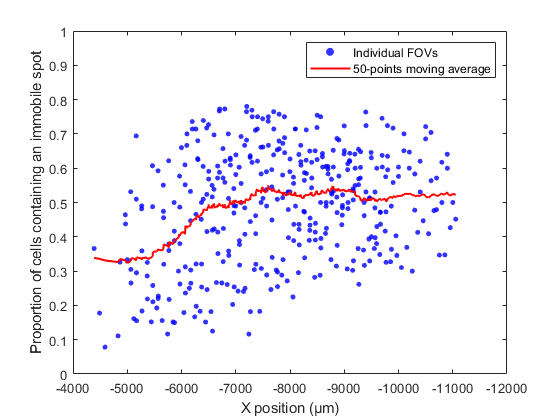

xdata = xpoints(~direction); % Keep only left to right
ydata = spotFracFOV(xpos_idx);
ydata = ydata(~direction);
ytrend = movmean(ydata, 50);

figure('Color', 'white')
hold on
scatter(xdata, ydata, 15, 'filled', 'MarkerFaceAlpha', 0.8, 'MarkerFaceColor', 'b');
plot(xdata, ytrend, 'LineWidth', 1.5, 'Color', 'r');
hold off
box on
set(gca, 'XDir','reverse')
xlabel('X position (µm)')
ylabel('Proportion of cells containing an immobile spot')
ylim([0 1])
legend('Individual FOVs', '50-points moving average')

### spotFrac vs X-position for each Y position

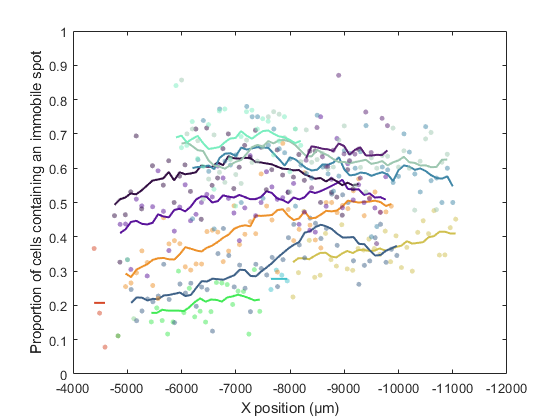

spotFracFOV_xpos = spotFracFOV(xpos_idx);
% cmap = rand(length(y_heights), 3);
% cmap = [linspace(0,1,length(y_heights))', zeros(length(y_heights),1), linspace(1,0,length(y_heights))'];

figure('Color', 'white')
hold on
for i = 1:length(y_heights)
    x_data = xpoints(ypoints == y_heights(i));
    y_data = spotFracFOV_xpos(ypoints == y_heights(i));
    scatter(x_data, y_data, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', cmap(i,:));
    plot(x_data, movmean(y_data, 10), 'LineWidth', 1.5, 'Color', cmap(i,:));
end
hold off
set(gca, 'XDir','reverse')
xlabel('X position (µm)')
ylabel('Proportion of cells containing an immobile spot')
ylim([0 1])
box on

### spotFrac vs X-position for each Y position (left to right direction only)

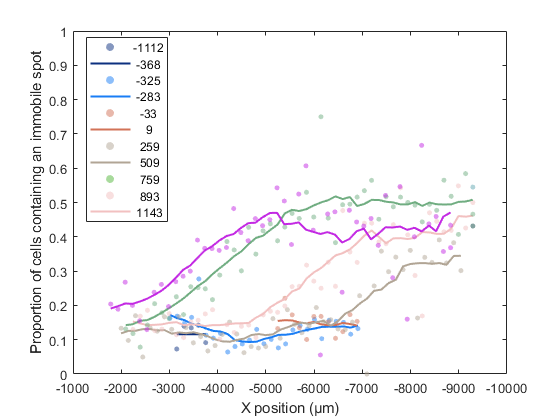

spotFracFOV_xpos = spotFracFOV(xpos_idx);
xinput = xpoints(~direction);
yinput = spotFracFOV_xpos(~direction);
ypoints_in = ypoints(~direction);

figure('Color', 'white')
hold on
for i = 1:length(y_heights)
    x_data = xinput(ypoints_in == y_heights(i));
    y_data = yinput(ypoints_in == y_heights(i));
    scatter(x_data, y_data, 15, 'filled', 'MarkerFaceAlpha', 0.5, 'MarkerFaceColor', cmap(i,:));
    plot(x_data, movmean(y_data, 10), 'LineWidth', 1.5, 'Color', cmap(i,:));
end
hold off
set(gca, 'XDir','reverse')
xlabel('X position (µm)')
ylabel('Proportion of cells containing an immobile spot')
ylim([0 1])
box on

### Heatmap of spot positions in the cell (normalised)

xypos = [dataSpots.normXpos dataSpots.normYpos];
mapData = xypos((xypos(:,1) < 2 & xypos(:,1) > -2) & (xypos(:,2) < 2 & xypos(:,2) > -2), :);

figure('Color', 'white')
hist3(mapData,'CdataMode','auto', 'edges', {-1:0.075:1 -2:0.15:2})
colormap(jet)
title('Position of bright spots (all cells)')
xlabel('% of major axis')
ylabel('% of minor axis')
colorbar
view(2)
xlim([-1 1])
ylim([-1*2 1*2])

### Heatmap of spot positions in the cell (normalised) for a specific Y position

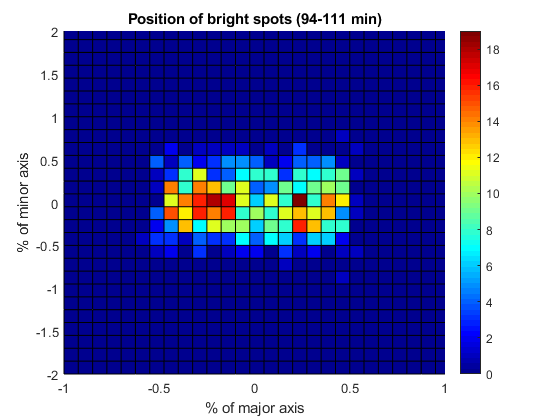

% Group selection (a group is defined as an array of points with the same Y
% position)
grp = 2;

fovs = unique(dataSpots.TrueIdx);
select_positions = fovs(y_groups == grp);
data_map = dataSpots(ismember(dataSpots.TrueIdx, select_positions), :);

xypos = [data_map.normXpos data_map.normYpos];
mapData = xypos((xypos(:,1) < 2 & xypos(:,1) > -2) & (xypos(:,2) < 2 & xypos(:,2) > -2), :);

figure('Color', 'white')
hist3(mapData,'CdataMode','auto', 'edges', {-1:0.075:1 -2:0.15:2})
colormap(jet)
% title(['Position of bright spots (group ' num2str(grp) ')'])
title(['Position of bright spots (94-111 min)'])
xlabel('% of major axis')
ylabel('% of minor axis')
colorbar
view(2)
xlim([-1 1])
ylim([-1*2 1*2])

### Heatmap timelapse video (exported)

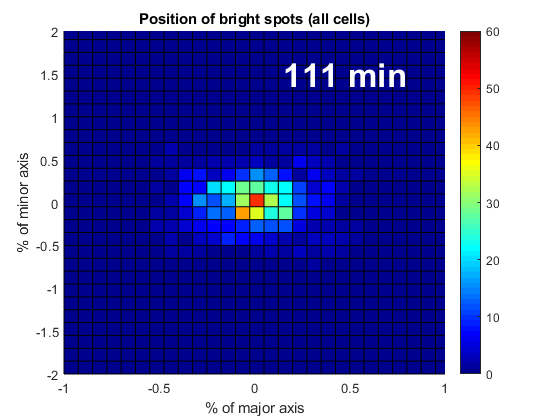

if exist('F', 'var')
    clear F
end

figure('Color', 'white')
for i = 1:length(timepoints)-20
    
    xypos = [dataSpots.normXpos(dataSpots.TrueIdx >= i & dataSpots.TrueIdx < i+20)...
        dataSpots.normYpos(dataSpots.TrueIdx >= i & dataSpots.TrueIdx < i+20)];
    mapData = xypos((xypos(:,1) < 2 & xypos(:,1) > -2) & (xypos(:,2) < 2 & xypos(:,2) > -2), :);
    
    hist3(mapData,'CdataMode','auto', 'edges', {-1:0.075:1 -2:0.15:2})
    hold on
    text(0.15, 1.5, [num2str(round(minutes(timepoints(i+10)))) ' min'],...
        'Color', 'w', 'FontWeight', 'b', 'FontSize', 25)
    hold off
    colormap(jet)
    title('Position of bright spots (all cells)')
    xlabel('% of major axis')
    ylabel('% of minor axis')
    colorbar
    view(2)
    xlim([-1 1])
    ylim([-1*2 1*2])
    caxis([0 60])
    
    F(i) = getframe(gcf) ;
    drawnow
end


% create the video writer with specified fps
writerObj = VideoWriter([Bacmman_folder dataset_name '/Heatmap_video.avi']);
writerObj.FrameRate = fps;
writerObj.Quality = 100;
% set the seconds per image
% open the video writer
open(writerObj);
% write the frames to the video
for i=2:length(F)
    % convert the image to a frame
    frame = F(i) ;
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);



### Heatmap timelapse video (exported) for a specific Y position

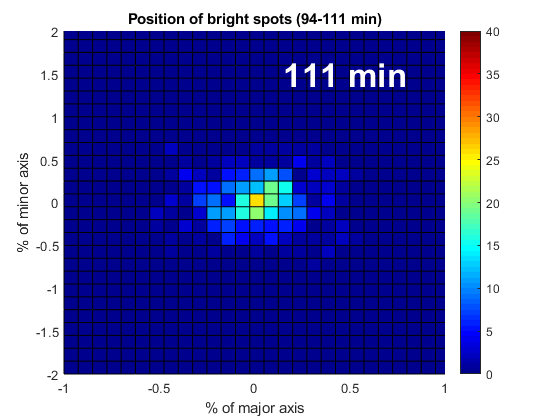

% Group selection (a group is defined as an array of points with the same Y
% position)
grp = 10;
window = 10;

fovs = unique(dataSpots.TrueIdx);
select_positions = fovs(y_groups == grp);
data_map = dataSpots(ismember(dataSpots.TrueIdx, select_positions), :);
data_time = timepoints(y_groups == grp);

if exist('F', 'var')
    clear F
end

figure('Color', 'white')
for i = 1:length(data_time)-window
    
    xypos = [data_map.normXpos(data_map.TrueIdx >= select_positions(i) & data_map.TrueIdx < select_positions(i+window))...
        data_map.normYpos(data_map.TrueIdx >= select_positions(i) & data_map.TrueIdx < select_positions(i+window))];
    mapData = xypos((xypos(:,1) < 2 & xypos(:,1) > -2) & (xypos(:,2) < 2 & xypos(:,2) > -2), :);
    
    hist3(mapData,'CdataMode','auto', 'edges', {-1:0.075:1 -2:0.15:2})
    hold on
    text(0.15, 1.5, [num2str(round(minutes(data_time(i+10)))) ' min'],...
        'Color', 'w', 'FontWeight', 'b', 'FontSize', 25)
    hold off
    colormap(jet)
    title('Position of bright spots (94-111 min)')
    xlabel('% of major axis')
    ylabel('% of minor axis')
    colorbar
    view(2)
    xlim([-1 1])
    ylim([-1*2 1*2])
    caxis([0 40])
    
    F(i) = getframe(gcf) ;
    drawnow
end


% create the video writer with specified fps
writerObj = VideoWriter([Bacmman_folder dataset_name '/Heatmap_video.avi']);
writerObj.FrameRate = fps;
writerObj.Quality = 100;
% set the seconds per image
% open the video writer
open(writerObj);
% write the frames to the video
for i=2:length(F)
    % convert the image to a frame
    frame = F(i) ;
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);